# Multi-Objective Optimal Control of a Mobile Robot with CasADi

The integrand of the energy costs is included into the ODE as a Mayer term.

## Initialization

close all
nNodes        = 60; % Number of shooting nodes 
nParetoPoints = 20; % Number of Pareto optimal solutions
nSteps        = 0;  % Number of intermediate multiple shooting steps
T_max         = 20; % Max time to reach the final state

## Setting up the problem

Generate an opti-object that stores all information about the optimization problem to be solved.

opt = casadi.Opti();
p_opts = struct;                  % Empty struct when Casadi plugin options remain unchanged
s_opt = struct('print_level', 0); % Stop pringting all information
opt.solver('ipopt', p_opts, s_opt)% Set solver, in our case IPOPT

T = opt.variable(1);                                % Time to reach the goal as a decision variable and cost           
x0  = [0 0 0 -135/180*pi 0 0]';                      % Initial condition, the mayer term is initialized with 0 and integrated from there
x   = [x0, opt.variable( 6, nNodes-1 )];            % The states are the initial state + all predicted states  
u   = opt.variable( 2, (nNodes-1) * (nSteps+1)+1 ); % Input for each state transition
dt  = T / ((nNodes-1) * (nSteps+1));                % Step size dt for the RK4 integrator

## Setting the equality constraints to respect the dynamics

Call the Runge-Kutta 4 integrator to connect following states with equality constraints

for iStep = 1:(nNodes-1)
    initial_step = (nSteps+1) * (iStep-1)+1;
    opt.subject_to( ms_step(x(:,iStep), u(:, initial_step:(initial_step + nSteps + 1)), dt) == x(:,iStep+1) )
end

## Box constraints

opt.subject_to( -45/180*pi <= x(5,:) <= 45/180*pi ) % box constraints on the steering angle
opt.subject_to( -20/180*pi <= u(2,:) <= 20/180*pi ) % box constraint turning velocity
opt.subject_to( -0.2 <= x(3,:) );                   % lower bound on velocity
opt.subject_to( x(1,:) <= 7.1 );                    % upper bound on x
opt.subject_to( -10 <= u(1,:) <= 5 )                % box constraint on the velocity
opt.subject_to( 1 <= T <= T_max )                   % reach the goal in at most T_max seconds

## Add cost functions

x_f    = [7, 5, 0, pi/2, 0]';     % Final state to reach
opt.subject_to(x(1:5,end) == x_f) % Constraint to reach the final state
cost_u = x(6, end);               % Approximation of the energy costs using the mayer term

## Find Extreme points, utopia point and nadir point

opt.minimize(T)
solT = opt.solve();

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        93
       nlp_g  |  29.00ms (311.83us)  29.95ms (322.08us)        93
  nlp_grad_f  |        0 (       0)        0 (       0)        27
  nlp_hess_l  | 744.00ms (  8.75ms) 751.60ms (  8.84ms)        85
   nlp_jac_g  | 224.00ms (  2.52ms) 222.06ms (  2.50ms)        89
       total  |   1.32 s (  1.32 s)   1.32 s (  1.32 s)         1


opt.minimize(cost_u)
solU = opt.solve();

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)       116
       nlp_g  |  36.00ms (310.34us)  35.70ms (307.77us)       116
  nlp_grad_f  |        0 (       0)        0 (       0)        40
  nlp_hess_l  | 849.00ms (  8.66ms) 849.99ms (  8.67ms)        98
   nlp_jac_g  | 253.00ms (  2.48ms) 253.64ms (  2.49ms)       102
       total  |   1.51 s (  1.51 s)   1.51 s (  1.51 s)         1



% Calculate Extreme points, Utopia point and Nadir point
EP = [solT.value([T, cost_u]); solU.value([T, cost_u])];
up = min(EP, [], 1);
np = max(EP, [], 1);

## Initialize Pascoletti-Serafini

l = opt.variable(1);
d = opt.parameter(1,2);
s = opt.parameter(1,2);
opt.subject_to(s+l*d >= ([T, cost_u]-up)./(np-up))
opt.minimize(-l);

## normalized NBI

EPnorm = (EP-up)./(np-up);
opt.set_value(d, -null(EPnorm(2,:)-EPnorm(1,:))')

s_pts_norm = get_starting_points(EPnorm, nParetoPoints);

sol_norm(1) = solT;
Jnorm = sol_norm(1).value([T, cost_u]);
for iSol = 2:(nParetoPoints-1)
    opt.set_value(s, s_pts_norm(iSol,:))

    opt.set_initial(u,  sol_norm(iSol-1).value( u))
    opt.set_initial(x,  sol_norm(iSol-1).value( x))
    opt.set_initial(T,  sol_norm(iSol-1).value( T))
    opt.set_initial(dt, sol_norm(iSol-1).value(dt))

    sol_norm(iSol) = opt.solve();
    Jnorm(iSol,:) = sol_norm(iSol).value([T, cost_u]);
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        36
       nlp_g  |  14.00ms (388.89us)  13.92ms (386.56us)        36
    nlp_grad  |   1.00ms (  1.00ms) 963.00us (963.00us)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        37
  nlp_hess_l  | 299.00ms (  8.54ms) 299.21ms (  8.55ms)        35
   nlp_jac_g  |  91.00ms (  2.46ms)  91.13ms (  2.46ms)        37
       total  | 501.00ms (501.00ms) 501.03ms (501.03ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        40
       nlp_g  |   9.00ms (225.00us)   8.96ms (223.92us)        40
    nlp_grad  |   1.00ms (  1.00ms)   1.07ms (  1.07ms)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        41
  nlp_hess_l  | 338.00ms (  8.67ms) 338.21ms (  8.67ms)        39
   nlp_jac_g  | 104.00ms (  2.54ms) 103.95ms (  2.54ms)        41
       tot

sol_norm(end+1) = solU;
Jnorm(end+1,:) = sol_norm(end).value([T, cost_u]);

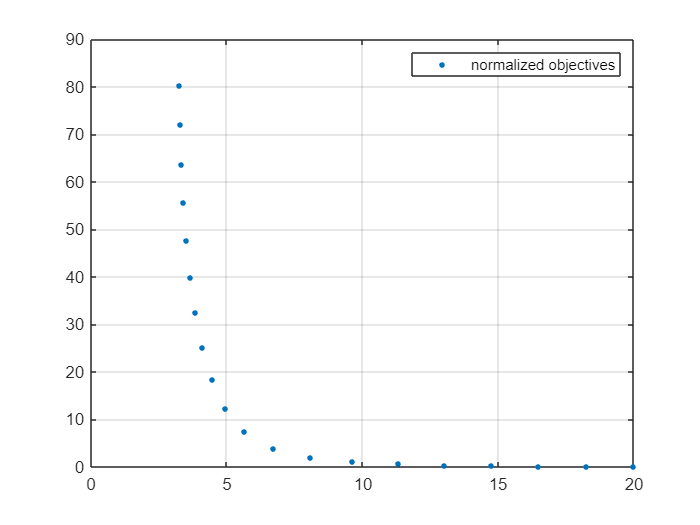

plot(Jnorm(:,1), Jnorm(:,2), '.', 'MarkerSize', 10)
legend("normalized objectives")
grid on

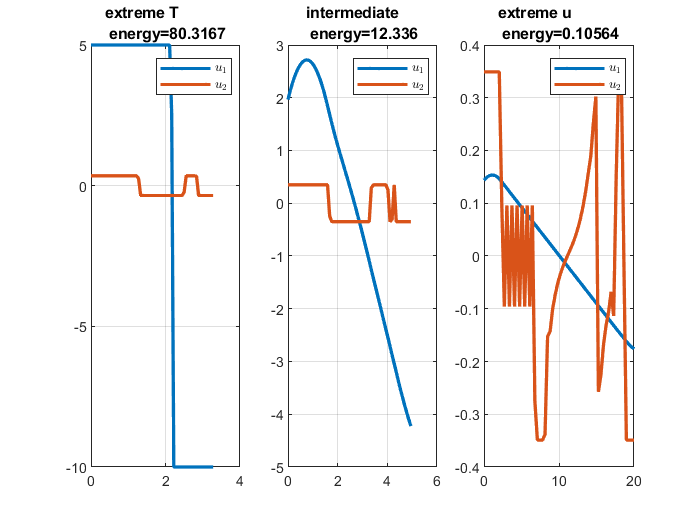

figure
subplot(1,3,1)
plot(0:(sol_norm(1).value(dt)*(nSteps+1)):sol_norm(1).value(T), sol_norm(1).value(u), 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("extreme T \newline energy=" + sol_norm(1).value(cost_u))
grid on

subplot(1,3,2)
plot(0:(sol_norm(round(nParetoPoints/2)).value(dt)*(nSteps+1)):sol_norm(round(nParetoPoints/2)).value(T), sol_norm(round(nParetoPoints/2)).value(u), 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("intermediate \newline energy=" + sol_norm(round(nParetoPoints/2)).value(cost_u))
grid on

subplot(1,3,3)
plot(0:(sol_norm(end).value(dt)*(nSteps+1)):sol_norm(end).value(T), sol_norm(end).value(u), 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("extreme u \newline energy=" + sol_norm(end).value(cost_u))
grid on

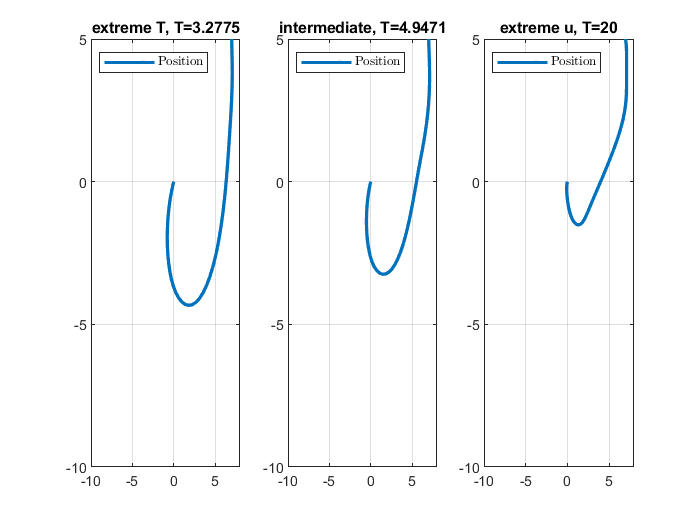


figure;
subplot(1,3,1)
plot(sol_norm(1).value(x(1,:)), sol_norm(1).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("extreme T, T=" + sol_norm(1).value(T))
xlim([-10 8])
ylim([-10 5])
grid on

subplot(1,3,2)
plot(sol_norm(round(nParetoPoints/2)).value(x(1,:)), sol_norm(round(nParetoPoints/2)).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("intermediate, T=" + sol_norm(round(nParetoPoints/2)).value(T))
xlim([-10 8])
ylim([-10 5])
grid on

subplot(1,3,3)
plot(sol_norm(end).value(x(1,:)), sol_norm(end).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("extreme u, T=" + sol_norm(end).value(T))
xlim([-10 8])
ylim([-10 5])
grid on

## Runge-Kutta 4 integrator

Here, we assume that u is not constant between two time steps, but linearly rises and falls. This is called first-order hold (FOH) instead of zero-order hold (ZOH), allowing for smoother u curves (not part of this lecture, but nice to know).

function x_end = ms_step(x0, u_series, dt)
% calculate one multiple shooting step with step size dt assuming FOH
% behaviour of u
import casadi.*

x0_rk = x0;
k = casadi.MX( size( x0, 1 ), 4 );

for i = 1:(size( u_series, 2 ) - 1)
    k(:,1) = robot_ode(x0_rk(:,end), u_series(:,i));
    k(:,2) = robot_ode(x0_rk(:,end) + dt / 2 * k(:,1), u_series(:,i)/2 + u_series(:,i+1)/2);
    k(:,3) = robot_ode(x0_rk(:,end) + dt / 2 * k(:,2), u_series(:,i)/2 + u_series(:,i+1)/2);
    k(:,4) = robot_ode(x0_rk(:,end) + dt * k(:,3), u_series(:,i+1));
    x0_rk  = [x0_rk, x0_rk(:,end) + dt / 6 * k * [1 2 2 1]'];
end

x_end = x0_rk(:, end);
end

## Robot ODE

Here, we include the integral term from the cost functions into the ODE so that the Integrator also integrates the integrand from the cost function. The final state will be the integrated cost function (Not part of the lecture, but nice to know).

function xdot = robot_ode(x, u)
    l = 1;
    xdot = [x(3)*cos( x(4) + x(5) ); x(3)*sin( x(4) + x(5) ); u(1); x(3) / l * sin( x(5) ); u(2); 0.5*u(1)^2];
end


function s_pts = get_starting_points(EP, nParetoPoints)
    weights = (linspace(0,1,nParetoPoints));
    weights = ([1-weights; weights]);
    s_pts = weights'*EP;
end